clc;
clear all;
close all;

## generate data

run ("Basics.m")

sys =
 
                 1.3 s + 1.333
  --------------------------------------------
  s^4 + 3.967 s^3 + 8.41 s^2 + 10.62 s + 8.756
 
Continuous-time transfer function.



fb = 2.4327

sysd =
 
  0.0004236 z^3 + 0.001167 z^2 - 0.000997 z - 0.0003069
  -----------------------------------------------------
      z^4 - 3.481 z^3 + 4.58 z^2 - 2.697 z + 0.5991
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



c =          0    0.0004    0.0012   -0.0010   -0.0003


d =     1.0000   -3.4807    4.5802   -2.6968    0.5991


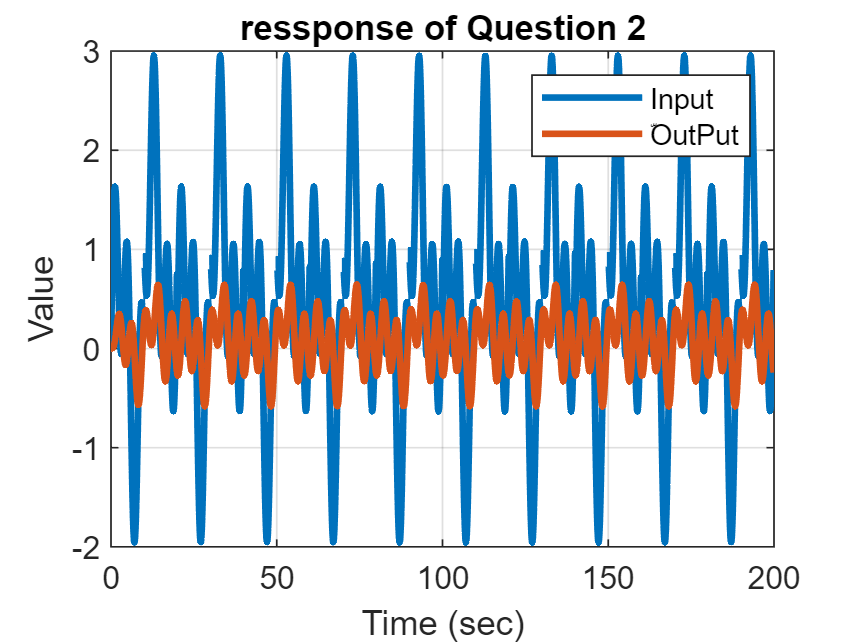

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tfinal=200;
t = 0:T_s:tfinal;
u = gensig('sine' , tfinal/20 , tfinal ,T_s)+gensig('sine' , tfinal/50 , tfinal ,T_s)+gensig('square' , tfinal/10 , tfinal ,T_s);
y = lsim(sysd  ,u ,t);
plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 2') ;
grid on
legend('Input' , 'ّOutPut') ;

## recursive least esquare estimation

N = numel(y) ;
%choose number of parameters
Parameters_in_den=4

Parameters_in_den = 4

Parameters_in_num=4

Parameters_in_num = 4

Nv=Parameters_in_num+Parameters_in_den

Nv = 8

theta(:,1:Nv) = zeros(Nv , Nv) ;
P = 1e12*eye(Nv) ;
phi=[];
Eror=zeros(1,N)

Eror =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


tic
for i = (max(Parameters_in_num,Parameters_in_den))+1:N
    phi(:,i) = [[y(i-1:-1:i-Parameters_in_den)]' , [u(i-1:-1:i-Parameters_in_num)]']';
    K = P*phi(:,i)*(1+phi(:,i)'*P*phi(:,i))^(-1) ;
    P = (eye(Nv) - K*phi(:,i)')*P ;
    theta(:,i) = theta(:,i-1) + K*(y(i) - phi(:,i)'*theta(:,i-1)); 
    Eror(i)=(Eror(i-1)+(y(i)-phi(:,i)'*theta(:,i))^2);
end
toc

Elapsed time is 0.045791 seconds.


theta1(:,1:Nv) = zeros(Nv , Nv) ;
P1 = 1e4*eye(Nv) ;
phi1=[];
Eror1=zeros(1,N)

Eror1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


tic
for i1 = (max(Parameters_in_num,Parameters_in_den))+1:N
    phi1(:,i1) = [[y(i1-1:-1:i1-Parameters_in_den)]' , [u(i1-1:-1:i1-Parameters_in_num)]']';
    K1 = P1*phi1(:,i1)*(1+phi1(:,i1)'*P1*phi1(:,i1))^(-1) ;
    P1 = (eye(Nv) - K1*phi1(:,i1)')*P1 ;
    theta1(:,i1) = theta1(:,i1-1) + K1*(y(i) - phi1(:,i1)'*theta1(:,i1-1)); 
    Eror1(i1)=(Eror1(i1-1)+(y(i)-phi1(:,i1)'*theta1(:,i1))^2);
end
toc

Elapsed time is 0.033440 seconds.


ident_dis1 = tf(theta((Parameters_in_num+1):end,end)' ,[1 -theta(1:Parameters_in_num ,end)'], T_s)

ident_dis1 =
 
  0.0004236 z^3 + 0.001167 z^2 - 0.000997 z - 0.0003069
  -----------------------------------------------------
      z^4 - 3.481 z^3 + 4.58 z^2 - 2.697 z + 0.5991
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



ident_dis2 = tf(theta1((Parameters_in_num+1):end,end)' ,[1 -theta1(1:Parameters_in_num ,end)'], T_s)

ident_dis2 =
 
  -0.1038 z^3 + 0.002156 z^2 - 0.13 z - 0.6243
  --------------------------------------------
  z^4 - 75.3 z^3 + 88.69 z^2 + 31.16 z - 49.13
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



ident_analog1 = d2c(ident_dis1)

ident_analog1 =
 
  1.416e-09 s^3 - 1.046e-08 s^2 + 1.3 s + 1.333
  ---------------------------------------------
  s^4 + 3.967 s^3 + 8.41 s^2 + 10.62 s + 8.756
 
Continuous-time transfer function.



ident_analog2 = d2c(ident_dis2)

ident_analog2 =
 
      -0.07719 s^4 + 1.765 s^3 - 81.98 s^2 + 804.3 s - 8503
  --------------------------------------------------------------
  s^5 - 27.47 s^4 + 407.8 s^3 - 1.981e04 s^2 - 9137 s - 3.568e04
 
Continuous-time transfer function.



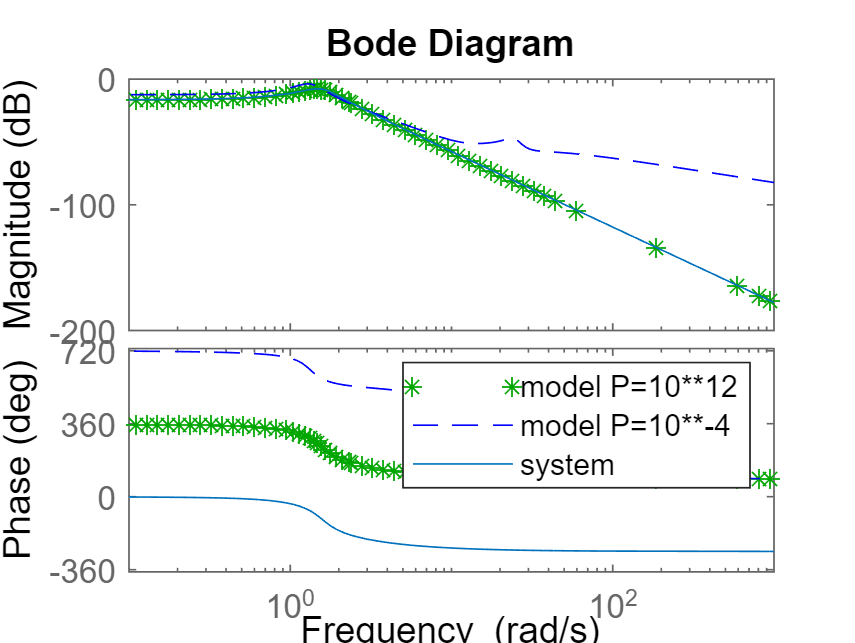

figure
bode(ident_analog1 ,'g*',ident_analog2,'b--',sys )
legend('model P=10**12','model P=10**-4','system')

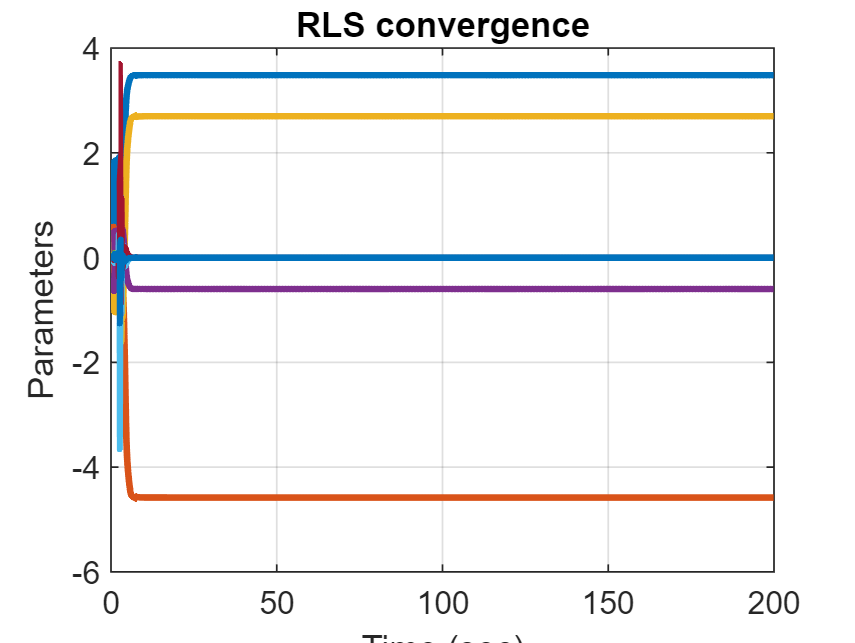

plot(t , theta(:,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('RLS convergence') ;
grid on

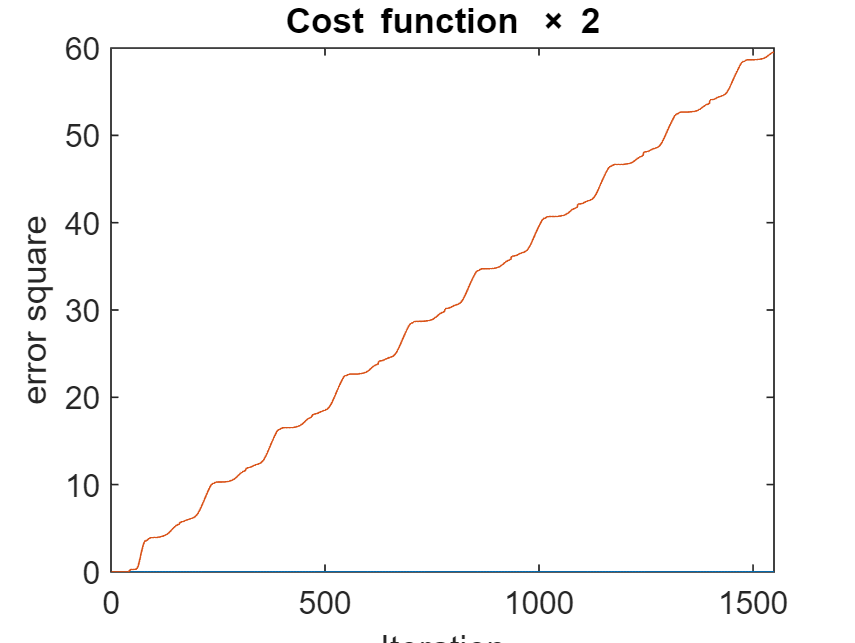

plot(1:1:N,Eror,1:1:N,Eror1)
xlabel('Iteration') ;
ylabel('error square') ;
title('Cost function \times 2') ;